
%%% 1. Construct portfolio frontier using 10 risky stocks in mean-standard
%%% deviation space and in the mean-variance space

std_vec = zeros(10,1)

std_vec =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:10
    std_vec(i) = std(ret_mat(:,i));
end


e_T = mean(ret_mat); % compute mean return of all stocks
e = e_T.'

e =     0.0096
    0.0254
    0.0218
    0.0137
    0.0122
    0.0162
    0.0179
    0.0196
    0.0206
    0.0023


v = cov(ret_mat);
I = ones(10,1)

I =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


I_T = I.'

I_T =      1     1     1     1     1     1     1     1     1     1



A = e_T * inv(v) * I;
B = e_T * inv(v) * e;
C = I_T * inv(v) * I;
D = B * C - A * A

D = 149.2648


g = (1/D)*(B*(inv(v)*I)-A*(inv(v)*e));
h = (1/D)*(C*(inv(v)*e)-A*(inv(v)*I));



number = 500

number = 500

p_rets = linspace(-0.01,0.03,number);

std_p = zeros(number,1);
w_p = zeros(10,1)

w_p =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


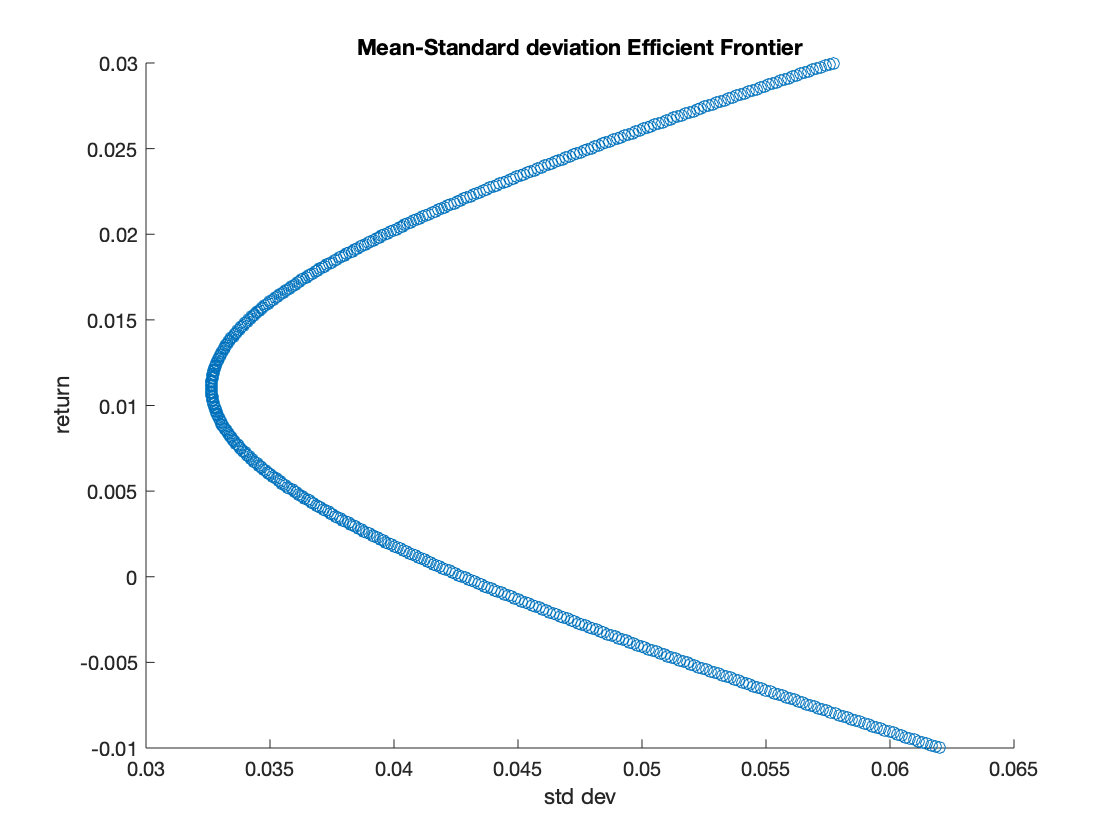

% compute w_p for all portfolios
for i = 1:number
    w_p = g + h * p_rets(i);
    std_p(i) = sqrt(w_p.' * v * w_p);
end

f1 = figure;
f2 = figure;
figure(f1);
hold on
scatter(std_p,p_rets)
%scatter(std_vec,e_T,"filled")
title("Mean-Standard deviation Efficient Frontier")
xlabel("std dev")
ylabel("return")

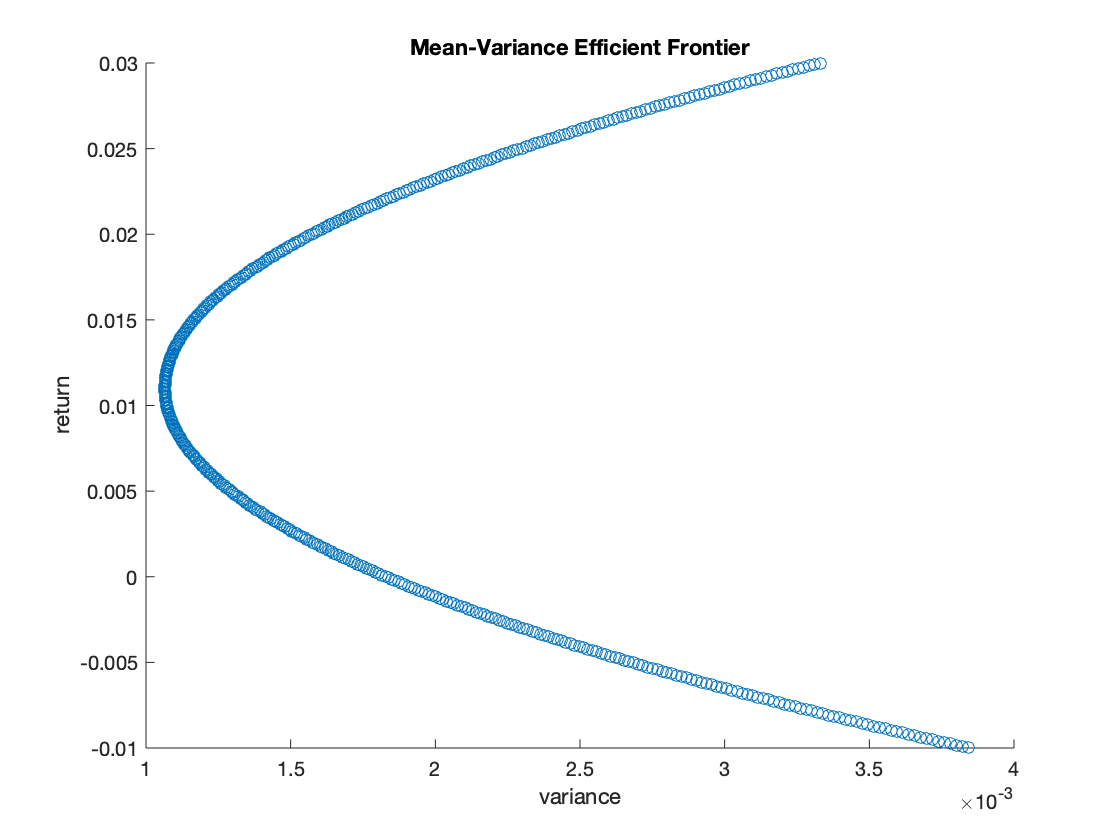

var_p = zeros(number,1);
for i = 1:number
    w_p = g + h * p_rets(i);
    var_p(i) = w_p.' * v * w_p;
end
figure(f2)
hold on
scatter(var_p,p_rets)
title("Mean-Variance Efficient Frontier")
xlabel("variance")
ylabel("return")

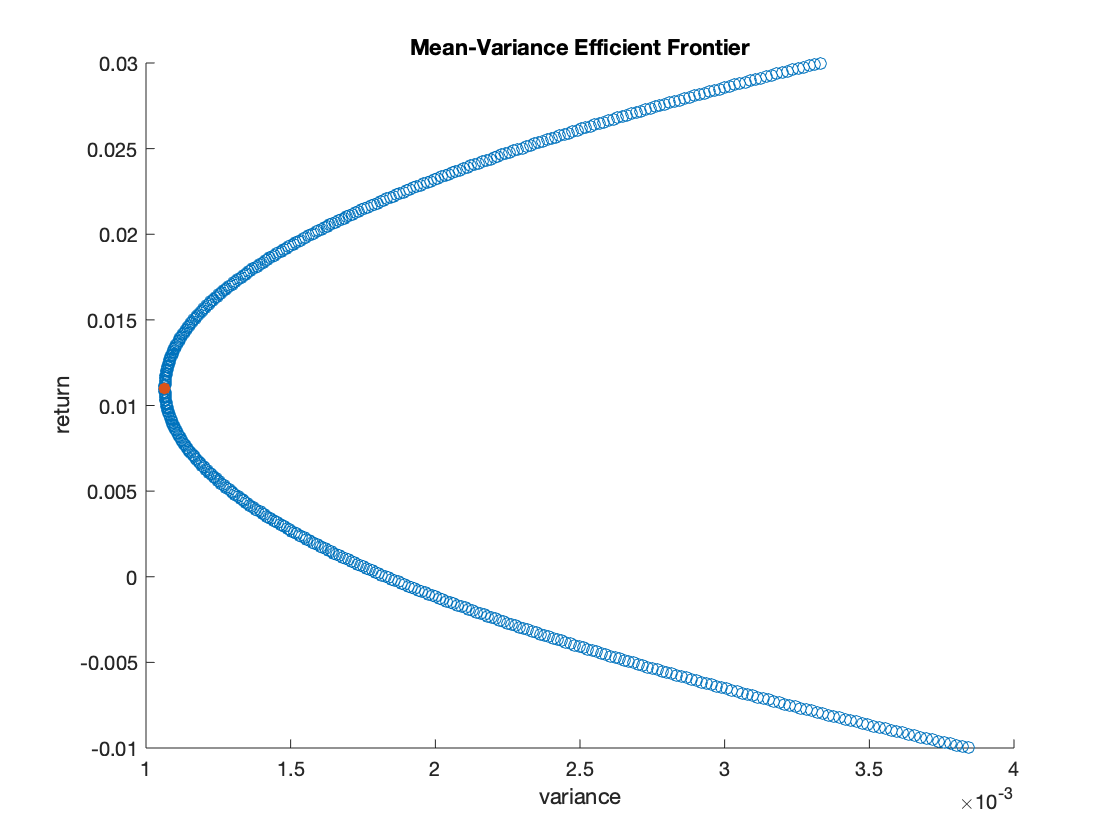

figure(f2)
scatter(1/C,A/C,"filled")

%%% 2. Plot SP500 and Nasdaq portfolio in the mean-standard deviation space
ret_sp = mean(sp500.Ret)

ret_sp = 0.0111

std_sp = std(sp500.Ret)

std_sp = 0.0391


ret_nas = mean(nasdaq.VarName2)

ret_nas = 0.0124

std_nas = std(nasdaq.VarName2)

std_nas = 0.0515

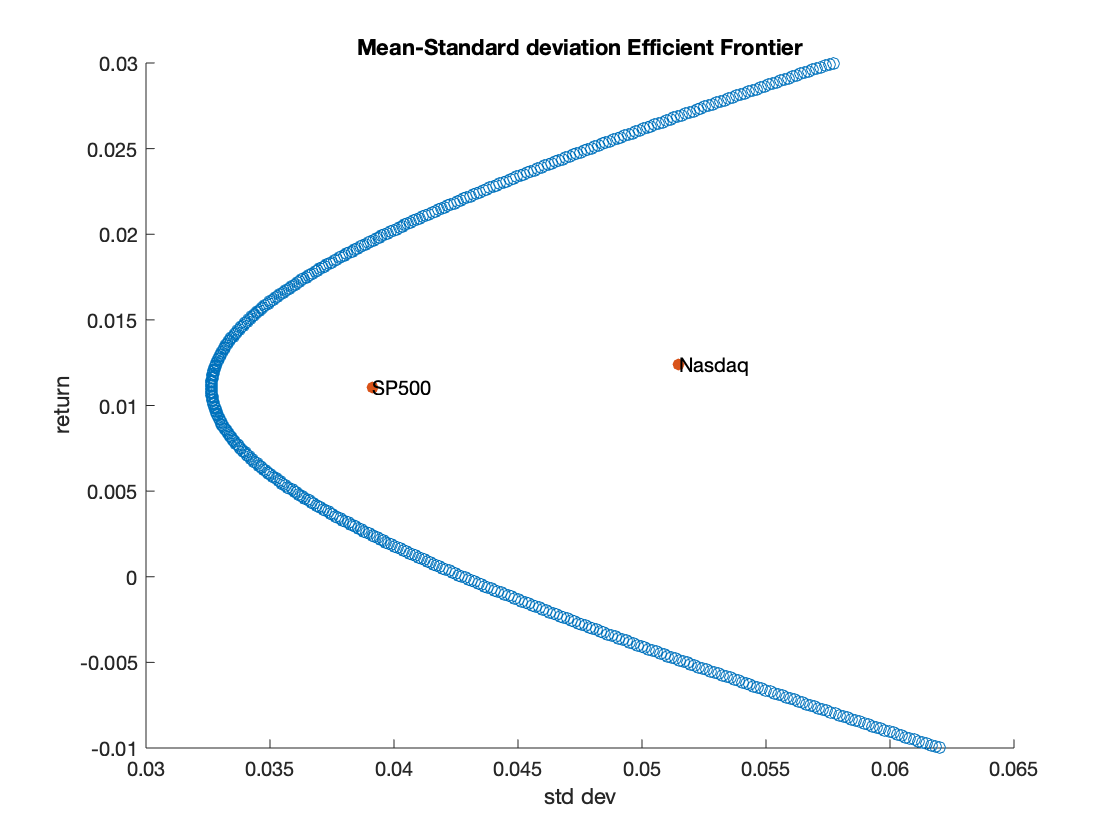

rets = [ret_sp;ret_nas];
stds = [std_sp;std_nas];
figure(f1)
scatter(stds,rets,"filled")
text(std_nas,ret_nas,"Nasdaq")
text(std_sp,ret_sp,"SP500")

%%% 3. Construct mvp and the equally weighted portfolio ewp. Show sigma(mvp,ewp)
%%% = sigma(mvp)^2
w_ewp = [0.1;0.1;0.1;0.1;0.1;0.1;0.1;0.1;0.1;0.1];
r_mvp = A/C;
w_mvp = g + h * r_mvp;
std_mvp = sqrt(1/C);
w_mvp = g + h * r_mvp;
r_ewp = e_T*w_ewp

r_ewp = 0.0159

std_ewp = sqrt(w_ewp.'* v * w_ewp)

std_ewp = 0.0416

std_mvp_ewp = cov(ret_mat*w_ewp,ret_mat*w_mvp)

std_mvp_ewp =     0.0017    0.0011
    0.0011    0.0011


%std_mvp_ewp = mean((ret_mat*w_ewp - r_ewp).*(ret_mat*w_mvp - r_mvp)) - r_mvp * r_ewp

%%% 4. Require a return that is 0.5% higher than r_ewp. How should she
%%% invest her money?
target_ret = r_ewp + 0.005; % if investor wants 0.5% higher than r_ewp return
w_p = g + h * target_ret;
var_p = w_p.' * v * w_p

var_p = 0.0017


w_p_2 = g + h * r_ewp;
var_p_2 = w_p_2.' * v * w_p_2

var_p_2 = 0.0012

%%% 5. out-of-sample test
e_in_T = mean(ret_mat(1:60,:));
e_in = e_in_T.';
v_in = cov(ret_mat(1:60,:));

w_p_in = g + h * target_ret;
var_p_in = w_p_in.' * v_in * w_p_in;

e_out_T = mean(ret_mat(61:120,:));
e_out = e_out_T.';
port_ret = e_out_T*w_p_in;
v_out = cov(ret_mat(61:120,:));
var_p_out = w_p_in.' * v_out * w_p_in;

%%% 6. Construct portfolio frontier with risk-free asset
r_f = mean(tbill.Ret)

r_f = 3.2062e-04

H = B-2*A*r_f+C*r_f^2;

number = 500

number = 500

p_rets = linspace(-0.01,0.03,number);

std_p_free = zeros(number,1);
w_p = zeros(10,1)

w_p =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


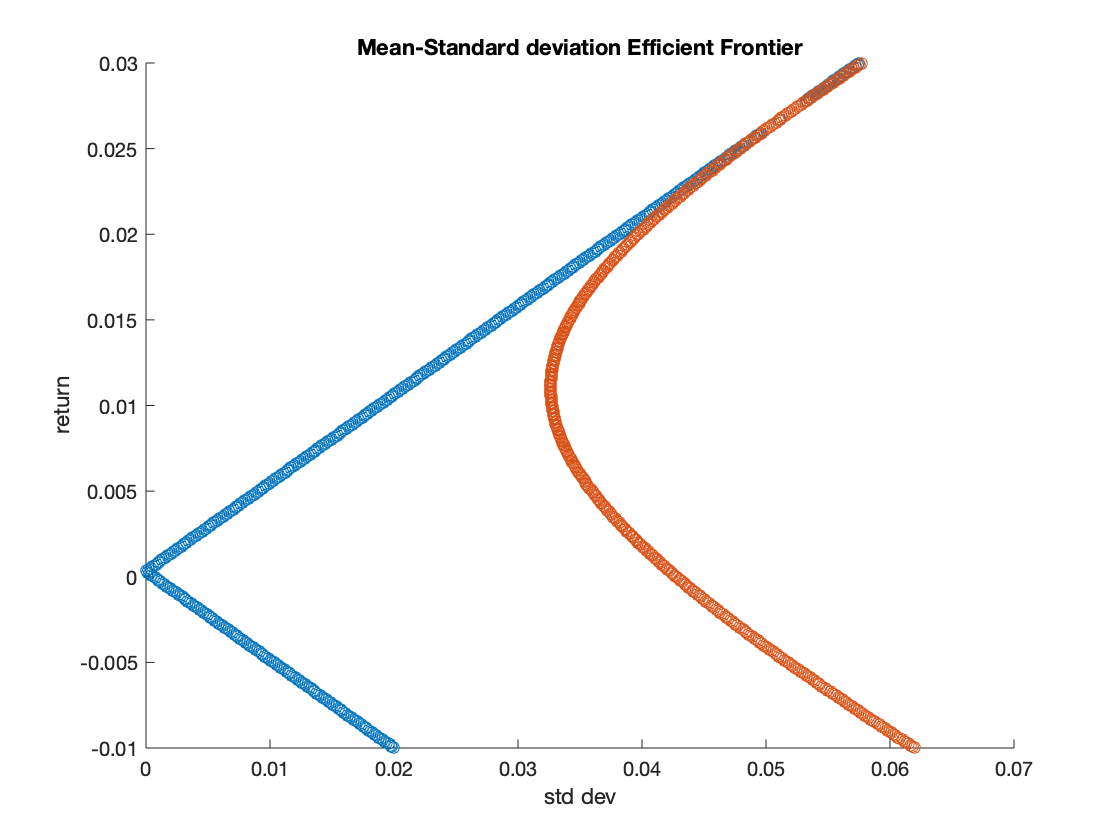

% compute w_p for all portfolios
for i = 1:number
    w_p = inv(v)*(e-r_f*I)*(p_rets(i)-r_f)/H;
    std_p_free(i) = sqrt(w_p.' * v * w_p);
end

f3 = figure;
figure(f3);
hold on
scatter(std_p_free,p_rets)
scatter(std_p,p_rets)

%scatter(std_vec,e_T,"filled")
title("Mean-Standard deviation Efficient Frontier")
xlabel("std dev")
ylabel("return")

%%% 7. Randomly pick a stock. Find the minimum variance portfolio that is
%%% uncorrelated with this stock

e_T_new = [e_T(8) r_mvp]; % compute mean return of all stocks
e_new = e_T_new.'

e_new =     0.0196
    0.0110


v_new = cov(ret_mat(:,8),ret_mat*w_mvp);
I_new = ones(2,1)

I_new =      1
     1


I_T_new = I_new.'

I_T_new =      1     1



A = e_T_new * inv(v_new) * I_new;
B = e_T_new * inv(v_new) * e_new;
C = I_T_new * inv(v_new) * I_new;
D = B * C - A * A

D = 6.9631


g = (1/D)*(B*(inv(v_new)*I_new)-A*(inv(v_new)*e_new));
h = (1/D)*(C*(inv(v_new)*e_new)-A*(inv(v_new)*I_new));

r_zc = A/C - (D/(C^2))/(mean(ret_mat(:,8))-(A/C))

r_zc = 0.0101

w_zc = g + h * r_zc;

%%% 8. For each of the three portfolios you constructed in problem 3 above,
%%% calculate the VaR's for the next month at the 1% probability under the
%%% following assumptions: 1) normal distribution 2) t(3) distribution 3)
%%% nonparametric bootstrap distribution with 10,000 replications with
%%% replacement. 
% Calculate VARs for equally weighted portfolios
wealth = 10000000;
e_port = e_T * w_ewp;

e_port = 0.0159

std_port = std(ret_mat*w_ewp);

std_port = 0.0416

norm_Var = (e_port - 2.33*(std_port))*wealth

norm_Var = -8.0914e+05


t_Var = (e_port - 4.541*(std_port))*wealth

t_Var = -1.7283e+06

sample_rets = datasample(ret_mat*w_ewp,10000);

sample_rets =     0.0545
    0.0555
    0.0386
   -0.0440
   -0.0072
    0.0214
    0.0895
    0.0106
    0.0391
    0.0302


sample_return = sample_rets * wealth;

sample_return = 	1.0e+06 *

    0.5450
    0.5551
    0.3862
   -0.4401
   -0.0720
    0.2143
    0.8948
    0.1057
    0.3911
    0.3019


sort_sample = sort(sample_return);

sort_sample = 	1.0e+06 *

   -1.2847
   -1.2847
   -1.2847
   -1.2847
   -1.2847
   -1.2847
   -1.2847
   -1.2847
   -1.2847
   -1.2847


ind = floor(1/100*length(sample_return));
sim_Var = sort_sample(ind)

sim_Var = -7.5713e+05

% Calculate VARs for equally weighted portfolios
wealth = 10000000;
e_port = e_T * w_mvp;
std_port = std(ret_mat*w_mvp);
norm_Var = (e_port - 2.33*(std_port))*wealth

norm_Var = -6.5032e+05


t_Var = (e_port - 4.541*(std_port))*wealth

t_Var = -1.3720e+06

sample_rets = datasample(ret_mat*w_mvp,10000);
sample_return = sample_rets * wealth;
sort_sample = sort(sample_return);
ind = floor(1/100*length(sample_return));
sim_Var = sort_sample(ind)

sim_Var = -7.3838e+05

% Calculate VARs for client target portfolio
wealth = 10000000;
e_port = e_T * w_p;
std_port = std(ret_mat*w_p);
norm_Var = (e_port - 2.33*(std_port))*wealth

norm_Var = -7.4705e+05


t_Var = (e_port - 4.541*(std_port))*wealth

t_Var = -1.6547e+06

sample_rets = datasample(ret_mat*w_p,10000);
sample_return = sample_rets * wealth;
sort_sample = sort(sample_return);
ind = floor(1/100*length(sample_return));
sim_Var = sort_sample(ind)

sim_Var = -5.4374e+05